# Summary of days (hour) by trial mean

clearvars -except kg

## Good kg idx

zx = 1;

%4:4 LD
ch1hourexp(zx).idx = [1 2 54];
    ch1hourexp(zx).hour = 4;
ch2hourexp(zx).idx = [1 2 55];
    ch2hourexp(zx).hour = 4;
    
    

%5:5 LD

    %zx = 2;
    zx = zx + 1;

ch1hourexp(zx).idx = [19 58]; %59
    ch1hourexp(zx).hour = 5;
ch2hourexp(zx).idx = [19 96]; %59
    ch2hourexp(zx).hour = 5;

 %6:6 LD
 
    %zx = 3;
    zx = zx + 1;

ch1hourexp(zx).idx = [8 32 33];
    ch1hourexp(zx).hour = 6;
ch2hourexp(zx).idx = [32 33];
    ch2hourexp(zx).hour = 6;

    %zx = 4;
    zx = zx + 1;

%8:8 LD
ch1hourexp(zx).idx = [27 25 26 35 36];
    ch1hourexp(zx).hour = 8;
ch2hourexp(zx).idx = [25 26 35 36];
    ch2hourexp(zx).hour = 8;

    %zx = 5;
    zx = zx + 1;

%10:10 LD
ch1hourexp(zx).idx= [6 7]; %61 outlier fish
    ch1hourexp(zx).hour = 10;
ch2hourexp(zx).idx = [6 7 60]; %61 outlier fish
    ch2hourexp(zx).hour = 10;

    %zx = 6;
    zx = zx + 1;

%12:12 LD
ch1hourexp(zx).idx = [12 14 16];
    ch1hourexp(zx).hour = 12;
ch2hourexp(zx).idx = [12 14 16 47];
    ch2hourexp(zx).hour = 12;

    %zx = 7;
    zx = zx + 1;

%13:13 LD
ch1hourexp(zx).idx = [31 28]; %29 - multimodal %30 bad data
    ch1hourexp(zx).hour = 13;
ch2hourexp(zx).idx = [28 31]; %29
    ch2hourexp(zx).hour = 13;

    %zx = 8;
    zx = zx + 1;

%20:20 LD
ch1hourexp(zx).idx = [37 38 40]; %39
    ch1hourexp(zx).hour = 20;
ch2hourexp(zx).idx = [37 38 40]; %39
    ch2hourexp(zx).hour = 20;

    %zx = 9;
    zx = zx + 1;

%24:24 LD
ch1hourexp(zx).idx = [56 11]; %10
    ch1hourexp(zx).hour = 24;
ch2hourexp(zx).idx = [11 10]; %57
    ch2hourexp(zx).hour = 24;
    
    %zx = 10;
    zx = zx + 1;

%48:48 LD
ch1hourexp(zx).idx = [3 4 5 44 46];
    ch1hourexp(zx).hour = 48;
ch2hourexp(zx).idx = [3 4 5 44]; %44 45
    ch2hourexp(zx).hour = 48;
    
ReFs = 10;    

Resample rate for cubic spline estimate. Units in samples per hour

ReFs = 10;

## Day summaries by channel and light transition

Darkdays = dark to light

Lightdays = light to dark

%channel 1 DarkDays
for k = 1:length(ch1hourexp)
    
    for kk = 1:length(ch1hourexp(k).idx)
         [dark1(k).h(kk).trial, dark1(k).h(kk).day] = KatieDayTrialDessembler(kg(ch1hourexp(k).idx(kk)), 1, ReFs);
        
    end
    
    [dark1(k).hourtim, dark1(k).meanoftrialmeans, dark1(k).ld] = k_daymeans(dark1(k).h);
    
end

triallength = 16

triallength = 16

triallength = 16

triallength = 20

triallength = 20

triallength = 24

triallength = 24

triallength = 24

triallength = 32

triallength = 32

triallength = 32

triallength = 32

triallength = 32

triallength = 40

triallength = 40

triallength = 48

triallength = 48

triallength = 48

triallength = 52

triallength = 52

triallength = 40

triallength = 40

triallength = 40

triallength = 48

triallength = 48

triallength = 96

triallength = 96

triallength = 96

triallength = 96

triallength = 96

triallength = 16

triallength = 16

triallength = 16

triallength = 20

triallength = 20

triallength = 24

triallength = 24

triallength = 24

triallength = 32

triallength = 32

triallength = 32

triallength = 32

triallength = 32

triallength = 40

triallength = 40

triallength = 48

triallength = 48

triallength = 48

triallength = 52

triallength = 52

triallength = 40

triallength = 40

triallength = 40

triallength = 48

triallength = 48

triallength = 96

triallength = 96

triallength = 96

triallength = 96

triallength = 96

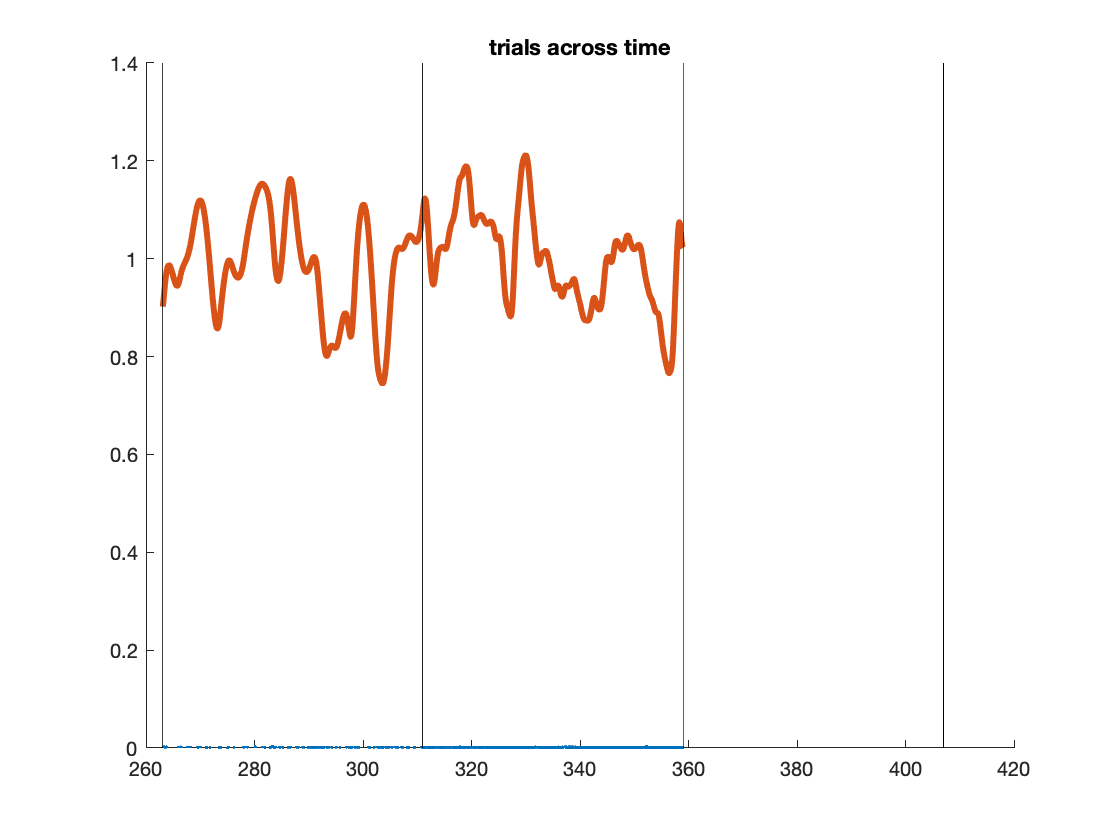

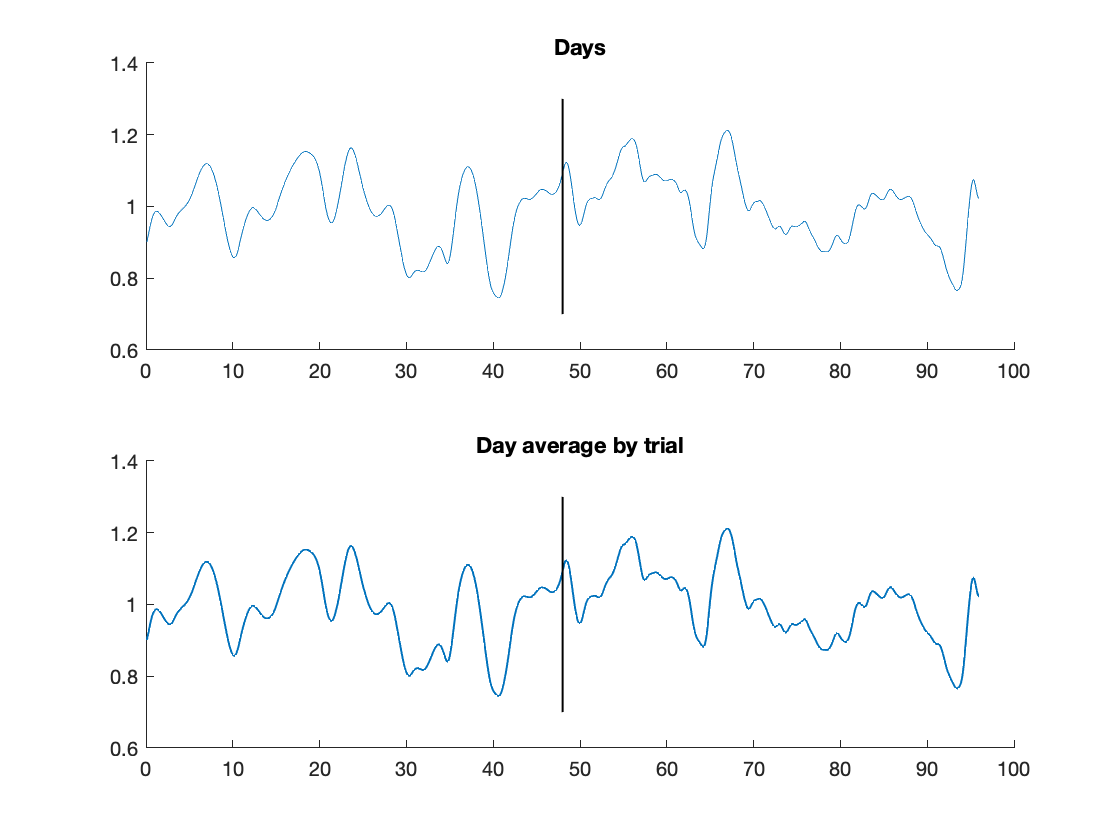

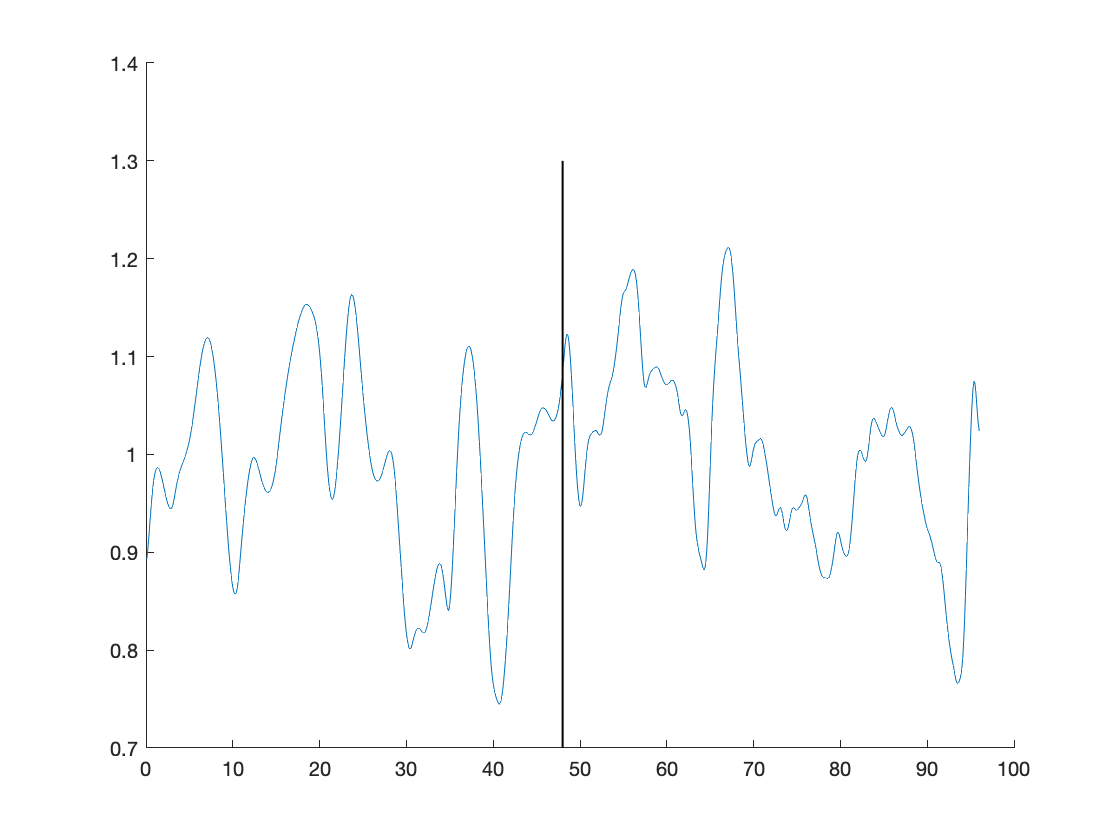

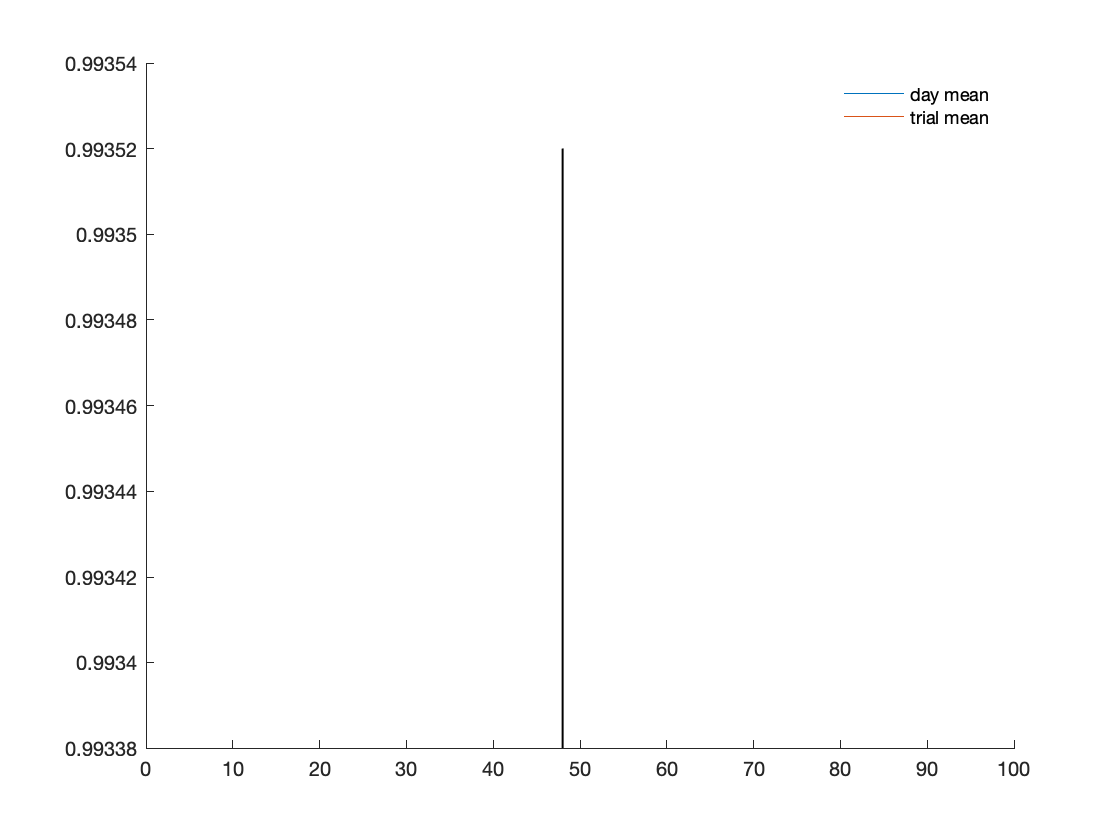

%channel 1 LightDays
for k = 1:length(ch1hourexp)
    
    for kk = 1:length(ch1hourexp(k).idx)
         [light1(k).h(kk).trial, light1(k).h(kk).day] = KatieLightDayTrialDessembler(kg(ch1hourexp(k).idx(kk)), 1, ReFs);
        
    end
    
    [light1(k).hourtim, light1(k).meanoftrialmeans, light1(k).ld] = k_daymeans(light1(k).h);
    
end

%channel 2 DarkDays

%just in case they are different
    clear k;
    clear kk;
    
for k = 1:length(ch2hourexp)
    
    for kk = 1:length(ch2hourexp(k).idk)
         [darkday2(kk).trial, darkday2(kk).day] = KatieDayTrialDessembler(kg(ch1hourexp(k).idk(kk)), 2, ReFs);
        
    end
    
    [dark2(k).hourtim, dark2(k).meanoftrialmeans, dark2(k).ld] = k_daydessembledplotter(darkday2);
    
end

%channel 2 DarkDays
for k = 1:length(ch2hourexp)
    
    for kk = 1:length(ch2hourexp(k).idk)
         [lightday2(kk).trial, lightday2(kk).day] = KatieLightDayTrialDessembler(kg(ch1hourexp(k).idk(kk)), 2, ReFs);
        
    end
    
    [light2(k).hourtim, light2(k).meanoftrialmeans, light2(k).ld] = k_daydessembledplotter(lightday2);
    
end

## Plots

close all; figure(314); clf; hold on; title('Dark to Light Channel 1');
set(gca,'XTick',-2*pi:pi:2*pi)
ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};


clear p;
clrs = hsv(length(dark1));
%colororder(clrs);

    for j = 1:length(dark1)

      
        ld(j,:) = dark1(j).ld;
        crosshour = (2*pi) / (2 * dark1(j).ld);
        p(j) = plot((pk(j).timforpi .* crosshour)-pi, pk(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end
 plot([0 0], ylim, 'k-');